#                                                         

## Evaluación 1 Análisis de datos geofísicos

**Estudiante:** Valentina Iturra Rosales 2021421947

**Profesor:** 

Rodrigo Abarca del Río

**Ayudantes:**

Javier Andrade

Scarlett Moraga

Alberto Pena

Poliana Leiva

## Manejo de datos

Recupere la serie t2mhs.txt, convierta la matriz a dos columnas con la columna 1 como el tiempo en fracción de año, tipo xxxx,xx y columna 2 como sus datos.

clc
clear all
close all

datos = load('t2mhs.txt');

%Para las dos columnas
datos2= [];
n=0;
years=datos(:,1);

for j=1:41
    for i=1:12
        n=n+1;
        datos2(n,2)=datos(j,(i+1));
    end
end
count=0;
for j=1980:2020
    for i=1:12
        count=count+1;
        datos2(count,1) = j + [i/12-1/24];
    end
end

## estadísticos

Obtener media, desviación estándar, Q1, Q2 y Q3 para su serie.

media = nanmean(datos2(:,2));
desviacion = nanstd(datos2(:,2));
Q1 = prctile(datos2(:,2),25);
Q2 = prctile(datos2(:,2),50);
Q3 = prctile(datos2(:,2),75);

## Gráficos

Realice un Boxplot para cada uno de los años, grafique todos en una misma figura.

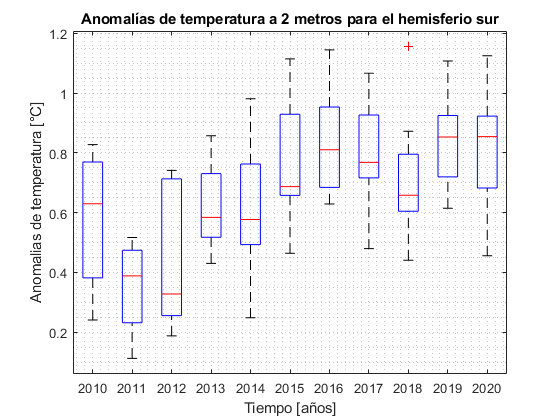

datos3 = datos';
datos3 = datos3(:,end-10:end);

figure()
boxplot(datos3(2:end,:),'labels',datos3(1,:))
grid minor
ylabel('Anomalias de temperatura [°C]')
xlabel('Tiempo [años]')
title('Anomalías de temperatura a 2 metros para el hemisferio sur')

Calcule para cada año su media, mediana, cuartiles, intercuartiles, desviación estándar y trimediana, y entréguelos en una tabla. Luego, grafique cada una de estas variables sobre su Boxplot correspondiente

a=0;
for i = 1:11
    a= a+1;
    media(a,1) = nanmean(datos3(2:end,i));
    mediana(a,1) = median(datos3(2:end,i));
    Q1(a,1) = prctile(datos3(2:end,i),25);
    Q2(a,1) = prctile(datos3(2:end,i),50);
    Q3(a,1) = prctile(datos3(2:end,i),75);
    IQR(a,1) = iqr(datos3(2:end,i));
    desviacion(a,1) = nanstd(datos3(2:end,i));
    trimean(a,1) = (Q1(a) + (2*Q2(a)) + Q3(a))/4;
    
end
tabla1 = table(media,mediana,Q1,Q2,Q3,IQR,desviacion,trimean)

tabla1 = 11×8 table
     media     mediana      Q1         Q2         Q3         IQR      desviacion    trimean
    _______    _______    _______    _______    _______    _______    __________    _______

    0.58445    0.62979    0.38162    0.62979    0.76939    0.38777     0.21784      0.60265
    0.34591    0.38833    0.23163    0.38833    0.47413     0.2425     0.14022       0.3706
    0.44546    0.32794    0.25546    0.32794    0.71267    0.45721      0.2314        0.406
    0.61881    0.58415    0.51757    0.58415    0.73024    0.21267     0.13564      0.60403
     0.6036    0.57691    0.49288    0.57691    0.76242    0.26954      0.2225      0.60228
    0.76604    0.68686    0.65773    0.68686    0.92889    0.27

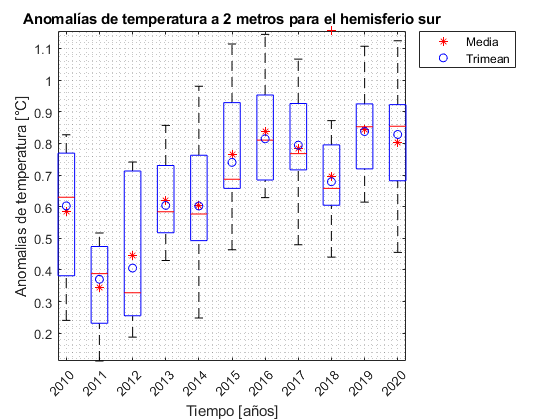

figure()
boxplot(datos3(2:end,:),'labels',datos3(1,:))
hold on
plot(media,'*r')
plot(trimean,'ob')
axis tight
grid minor
legend('Media','Trimean','Location','bestoutside')
ylabel('Anomalias de temperatura [°C]')
xlabel('Tiempo [años]')
title('Anomalías de temperatura a 2 metros para el hemisferio sur')

## Realice la media anual, para cada año, y enseguida calcule el histograma

correspondiente a la media de todos los años, utilizando la fórmula de ancho ideal.Compare con el Boxplot de todos los años

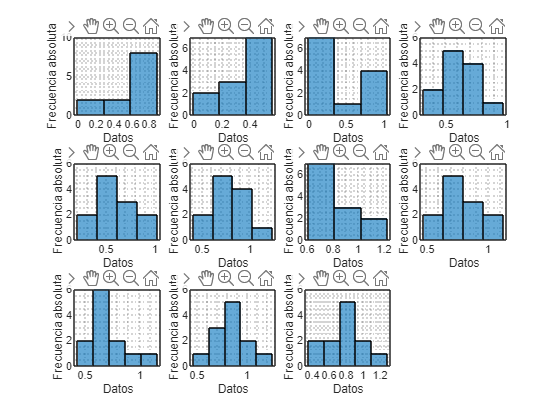

%Notemos que la media ha sido caluada anteriormente
figure()
for i=1:11
    h(i) = (2.6 * IQR(i))/(length(datos(2:end,i)))^(1/3);
    subplot(3,4,i)
    histogram(datos3(2:end,i),'BinWidth',h(i));
    title(datos3(1,i))
    ylabel('Frecuencia absoluta')
    xlabel('Datos')
    grid minor
end

## Ahora con la serie entregada t2m_1d.txt realice una interpolación en 1-D de tipo

"cubico” utilizando la función interp1 , para el dato NaN presente en el año 2005.


datosn = load('t2m_1d.txt');

ee = ~isnan(datosn(:,2));
idx = find(ee == 1);

datos_sn = datosn(idx,:);

x = datos_sn(:,1); %Fechas sin NaN
v = datos_sn(:,2); %Datos sin NaN
xq = datosn(:,1); %Fechas incluyendo NaN

ps = interp1(x,v,xq,'cubic');

## Luego con la serie t2m_nan.txt realice una interpolación en 2-D igualmente de tipo

"cubico”, utilizando la función griddata. Grafique el año 2005 para ambos casos en una sola figura, compare y comente las diferencias. 

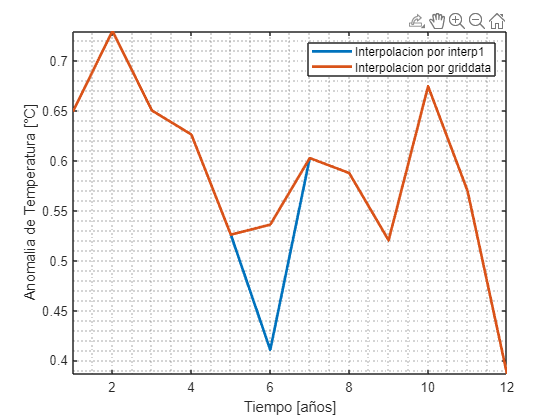

datosm = load('t2m_nan.txt');

B = datosm(:,2:13);

[col,fila]=meshgrid((1:12),1:41); 
%ES IMPORTANTE QUE X ES COLUMNAS E Y ES FILAS

ee = ~isnan(B);
idx = find(ee == 1);

datoss = griddata(col(idx),fila(idx),B(idx),col,fila); %La nueva matriz con el dato cambiado

figure()
plot(datoss(26,:),'LineWidth',2)
hold on
plot(ps(301:312,:),'LineWidth',2')
axis tight
grid minor
xlabel('Tiempo [años]')
ylabel('Anomalia de Temperatura [°C]')
legend('Interpolacion por interp1','Interpolacion por griddata')

Podemos notar que al interpolar el año 2005 por interp 1 se agregan valores que de alguna forma logran hacer que la grafica siga un mismo ciclo o serie, pero se corre el riesgo de que estos se alejen mucho de los valores esperados. En este caso griddata entrega una mejor intepolación.

## Se le es entregada la serie t2m_1d.txt, convierta este archivo de dos columnas a

una matriz de 41x13, con la primera columna que corresponda a los años y las 12 restantes a cada uno de los meses (No es necesario haber interpolado anteriormente). 

datos = load('t2m_1d.txt');

A(:,1) = [1980:2020];
for i = 1:12
    A(:,i+1) = datos((41*i)-40:41*i,2);
end

## Con el archivo andm_NaN.txt, realice una interpolación 2-D utilizando pesos (dados

por usted mismo) a los archivos. Tenga en consideración la distribución de pesos considerando que las columnas corresponden a los meses y las filas a los años, qué valores tendrán más influencia en su valor interpolado. Justifique su distribución de pesos y grafique cada año interpolado. 

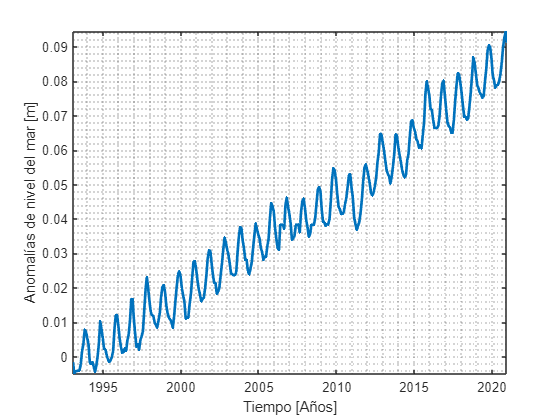

datos = load('andm_NaN.txt');

ee = ~isnan(datos);
[fila,columna] = find(ee == 0);

for i = 1 : length(fila)
    vca = datos(fila(i),columna(i)-1); %Valor cercano, el mes anterior
    vcb = datos(fila(i),columna(i)+1); %Valor cercano, el mes posterior
    mediac = (vca+vcb)/2;
    peso1 = mediac * 0.7;

    vla = datos(fila(i)-10,columna(i)); %Valor lejano, el mismo mes 10 años antes
    vlb = datos(fila(i)+10,columna(i)); %Valor lejano, el mismo mes 10 años despues
    medial = (vla+vlb)/2;
    peso2 = medial * 0.3;

    dato = peso1 + peso2;

    datos(fila,columna) = dato;
end

%Para las dos columnas
datos2= [];
n=0;
years=datos(:,1);

for j=1:28
    for i=1:12
        n=n+1;
        datos2(n,2)=datos(j,(i+1));
    end
end
count=0;
for j=1993:2020
    for i=1:12
        count=count+1;
        datos2(count,1) = j + [i/12-1/24];
    end
end

figure()
        plot(datos2(:,1),datos2(:,2),'LineWidth',2)
        axis tight
        grid minor
        xlabel('Tiempo [Años]')
        ylabel('Anomalías de nivel del mar [m]')

Utilicé el mes anterior y posterior para un peso del 70% pues son los mas cercanos al valor y el mismo mes 10 años antes y 10 años despues para asignarle un peso del 30% pues son mas lejanos, es razon de que tengan menos peso.

## Realice con lo obtenido 3 regresiones (de grado 1 a 3) para su serie obtenida,

comente a su criterio cuál es mejor con su respectivo error, dibujado y el error cuadrático medio. 

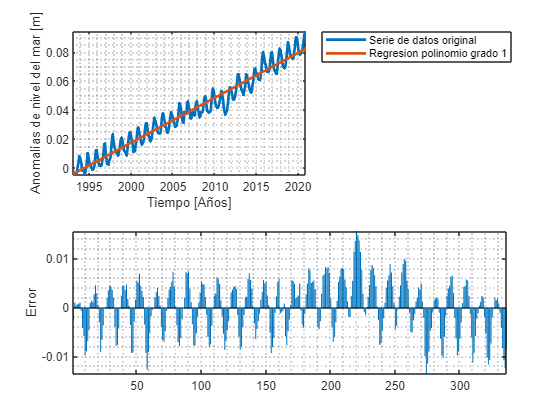

%Para las dos columnas

pp1 = polyfit(datos2(:,1),datos2(:,2),1);
pv1 = polyval(pp1,datos2(:,1));
Error= pv1 - datos2(:,2);
dif_cuadrado = Error.^2;
mse = sum(dif_cuadrado)/length(datos2(:,2));

figure()
    subplot(2,1,1)
        plot(datos2(:,1),datos2(:,2),'LineWidth',2)
        hold on
        plot(datos2(:,1),pv1,'LineWidth',2)
        axis tight
        grid minor
        xlabel('Tiempo [Años]')
        ylabel('Anomalías de nivel del mar [m]')
        legend('Serie de datos original','Regresion polinomio grado 1','Location','bestoutside')
    subplot(2,1,2)
        bar(Error)
        ylabel('Error')
    axis tight
            grid minor

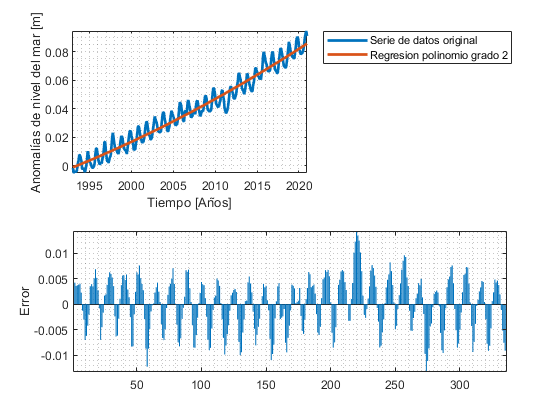


pp2 = polyfit(datos2(:,1),datos2(:,2),2);
pv2 = polyval(pp2,datos2(:,1));
Error2 = pv2 - datos2(:,2);
dif_cuadrado = Error2.^2;
mse2 = sum(dif_cuadrado)/length(datos2(:,2));


figure()
    subplot(2,1,1)
        plot(datos2(:,1),datos2(:,2),'LineWidth',2)
        hold on
        plot(datos2(:,1),pv2,'LineWidth',2)
        axis tight
        xlabel('Tiempo [Años]')
        ylabel('Anomalías de nivel del mar [m]')
        legend('Serie de datos original','Regresion polinomio grado 2','Location','bestoutside')
                grid minor
    subplot(2,1,2)
        bar(Error2)
        ylabel('Error')
    axis tight
        grid minor

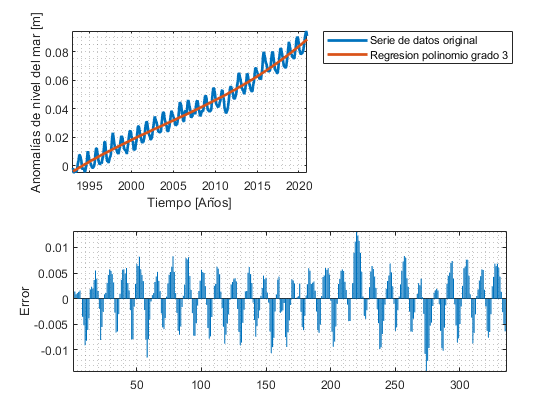


pp3 = polyfit(datos2(:,1),datos2(:,2),3);
pv3 = polyval(pp3,datos2(:,1));
Error3 = pv3 - datos2(:,2);
dif_cuadrado = Error3.^2;
mse3 = sum(dif_cuadrado)/length(datos2(:,2));


figure()
    subplot(2,1,1)
        plot(datos2(:,1),datos2(:,2),'LineWidth',2)
        hold on
        plot(datos2(:,1),pv3,'LineWidth',2)
        axis tight
        xlabel('Tiempo [Años]')
        ylabel('Anomalías de nivel del mar [m]')
        legend('Serie de datos original','Regresion polinomio grado 3','Location','bestoutside')
                grid minor
    subplot(2,1,2)
        bar(Error3)
        ylabel('Error')
    axis tight
            grid minor